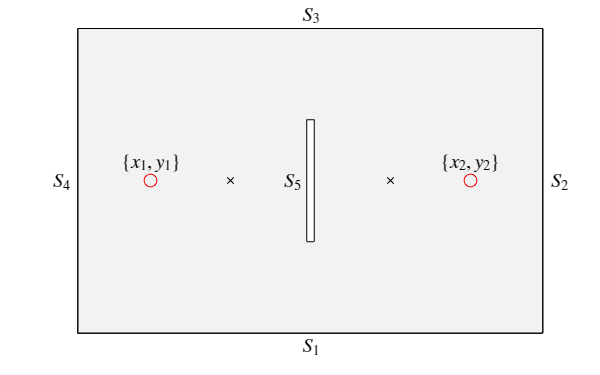

clear
clc

L = 400;
H = 250;
Lc = 100;
Tc = 6.5;

s1.x = 62.5;
s1.y = H/2;
s2.x = L - s1.x;
s2.y = H/2;

v1.x = 131.25;
v1.y = H/2;
v2.x = L - v1.x;
v2.y = v1.y;
v3.x = 151.39;
v3.y = 76.39;
v4.x = L - v3.x;
v4.y = H - v3.y;

fg = figure("Position",[0,0,L,H]);
xticks(-1); yticks(-1);
xlim([0,400])
ylim([0,250])
hold on
sz = 40;
scatter(s1.x, s1.y,sz, 'ro')
scatter(s2.x, s2.y,sz, 'ro')
scatter(v1.x,v1.y,sz/2,'kx')
scatter(v2.x,v2.y,sz/2,'kx')
% scatter(v3.x,v3.y,sz,'ko')
% scatter(v4.x,v4.y,sz,'ko')
fill([0,0,L,L],[0,H,H,0], ...
    [0,0,0],"FaceAlpha",0.05)
fill([L/2-Tc/2,L/2-Tc/2,L/2+Tc/2,L/2+Tc/2], ...
    [H/2-Lc/2,H/2+Lc/2,H/2+Lc/2,H/2-Lc/2], ...
    [1,1,1],"FaceAlpha",1)
hold off
grid off
box on

text(L/2,0,"$S_1$", ...
    "VerticalAlignment","top", ...
    "HorizontalAlignment","center", ...
    "Interpreter","latex")
text(L+5,H/2,"$S_2$", ...
    "HorizontalAlignment","left", ...
    "Interpreter","latex")
text(L/2,H,"$S_3$", ...
    "VerticalAlignment","bottom", ...
    "HorizontalAlignment","center", ...
    "Interpreter","latex")
text(-5,H/2,"$S_4$", ...
    "HorizontalAlignment","right", ...
    "Interpreter","latex")
text(L/2 - Tc,H/2,"$S_5$", ...
    "HorizontalAlignment","right", ...
    "Interpreter","latex")

text(s1.x,s1.y+5,"$\{x_1, y_1\}$", ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom", ...
    "Interpreter","latex")
text(s2.x,s2.y+5,"$\{x_2, y_2\}$", ...
    "HorizontalAlignment","center", ...
    "VerticalAlignment","bottom", ...
    "Interpreter","latex")

saveas(fg,"ProblemDefinition","svg")